%Clear all the memory and the variables
clear all
clc

%Number of Steps :
m = 3;

%Non - Stepped Joint
to_njs = 0.32; 
ti_njs = 0.25; 
c_njs = 1.5;

%Outer Adherend Properties
to = [0.12,0.22,0.32];
Eo = 15e6; 

%Inner Adherend Properties
ti = [0.25,0.15,0.05];
Ei = 17e6;

%Adhesive Properties 
Ga = 135e3; 
ta = 0.005; 

%Width of the adhesive
c = [0.5,0.5,0.5];

%Applied external force
Nx = 1500;

%Adhesive shear strength
Tau_ult = 3500; 

%Unknown Forces
N = zeros(m-1,1);

%********Problem 1 (a,b,c)***************************

[Coefficient_global] = Coefficient(m,Eo,Ei,Ga,to,ti,ta,c)

Coefficient_global =     8.9558   -0.1138
   -0.1138   10.4487


[B] = EquationConstant(m,Eo,Ei,Ga,to,ti,ta,c,Nx)

B = 	1.0e+04 *

    0.5593
    1.1369


N = inv(Coefficient_global)*B

N = 	1.0e+03 *

    0.6384
    1.0951


No =          0
   40.5283
   77.4454
  111.0798
  141.7310
  169.6718
  195.1507
  218.3946
  239.6103
  258.9866


No = 	1.0e+03 *

    0.6384
    0.6566
    0.6733
    0.6886
    0.7027
    0.7157
    0.7276
    0.7386
    0.7488
    0.7583


No = 	1.0e+03 *

    1.0951
    1.1162
    1.1349
    1.1514
    1.1660
    1.1789
    1.1904
    1.2005
    1.2094
    1.2174


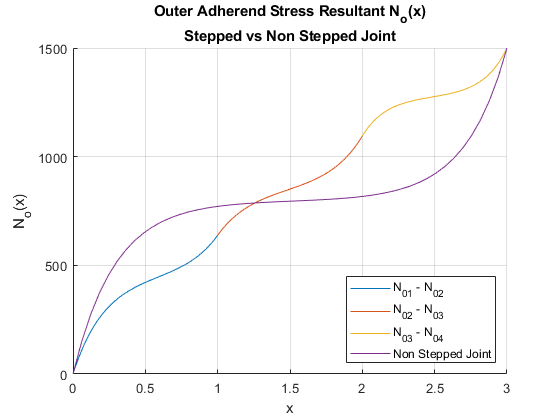

PlotNo(m,Eo,Ei,Ga,to,ti,ta,c,Nx,N,to_njs,ti_njs,c_njs)


%********Problem 1 (d)***************************
% N_trial = 1;
% [tau_maximum_c,tau_maximum_mc] = CohesiveFailureLoad(m,Eo,Ei,Ga,to,ti,ta,c,N_trial);
% N_trial = Tau_ult/max(max(tau_maximum_mc,tau_maximum_c));
% [tau_maximum_c,tau_maximum_mc] = CohesiveFailureLoad(m,Eo,Ei,Ga,to,ti,ta,c,N_trial);
% 
% fprintf("Maximum Load that need to be applied for cohesive failure is %7.4f",N_trial)
% fprintf("Maximum shear stress at the failure load is (x = c) %7.4f , %7.4f, %7.4f",tau_maximum_c)
% fprintf("Maximum shear stress at the failure load is (x = -c) %7.4f , %7.4f, %7.4f",tau_maximum_mc)
% 
% [Coefficient_global] = Coefficient(m,Eo,Ei,Ga,to,ti,ta,c);
% [B] = EquationConstant(m,Eo,Ei,Ga,to,ti,ta,c,N_trial);
% N = inv(Coefficient_global)*B;
% PlotNo(m,Eo,Ei,Ga,to,ti,ta,c,N_trial,N,to_njs,ti_njs,c_njs);

%********Problem 1 (d - Non Stepped Joint)***************************
% N_trial = 1;
% [tau_njs_maximum_c,tau_njs_maximum_mc] = NonSteppedJointCohesiveFailure(Ga,Ei,Eo,ta,to_njs,ti_njs,N_trial,c_njs);
% N_trial = Tau_ult/max(max(tau_njs_maximum_c,tau_njs_maximum_mc));
% [tau_njs_maximum_c,tau_njs_maximum_mc] = NonSteppedJointCohesiveFailure(Ga,Ei,Eo,ta,to_njs,ti_njs,N_trial,c_njs);
% fprintf("Maximum Load that need to be applied for cohesive failure is %7.4f",N_trial)
% fprintf("Maximum shear stress at the failure load is (x = c) %7.4f",tau_njs_maximum_c)
% fprintf("Maximum shear stress at the failure load is (x = -c) %7.4f",tau_njs_maximum_mc)
% 
% [Coefficient_global] = Coefficient(m,Eo,Ei,Ga,to,ti,ta,c);
% [B] = EquationConstant(m,Eo,Ei,Ga,to,ti,ta,c,N_trial);
% N = inv(Coefficient_global)*B;
% PlotNo(m,Eo,Ei,Ga,to,ti,ta,c,N_trial,N,to_njs,ti_njs,c_njs);


function [Coefficient_global] = Coefficient(m,Eo,Ei,Ga,to,ti,ta,c)
    k = m+1;
    %Initializing the global matrix
    Coefficient_global = zeros(k,k);
    for e = 1:k-1
        lambda = sqrt((Ga/ta)*((1/(Eo*to(e)))+(1/(Ei*ti(e)))));
        alpha = (lambda*tanh(lambda*c(e)))/2;
        beta = lambda/(2*tanh(lambda*c(e)));
        Coefficient_local = [alpha + beta alpha - beta ; alpha - beta alpha + beta];
        Coefficient_global(e:e+1, e:e+1) = Coefficient_global(e:e+1, e:e+1) + Coefficient_local;
    end
    Coefficient_global = TrimFirstAndLastColumnRows(Coefficient_global,m);
end

function [B] = EquationConstant(m,Eo,Ei,Ga,to,ti,ta,c,Nx)
    B = zeros(m-1,1);
    lambda = zeros(m,1);
    Co = zeros(m,1);
    alpha = zeros(m,1);
    beta = zeros(m,1);
    
    for i = 1:m
        lambda(i) = sqrt((Ga/ta)*((1/(Eo*to(i)))+(1/(Ei*ti(i)))));
        Co(i) = (Ga*Nx)/(Ei*ti(i)*ta);
        alpha(i) = (lambda(i)*tanh(lambda(i)*c(i)))/2;
        beta(i) = lambda(i)/(2*tanh(lambda(i)*c(i)));
    end
    for e = 1:m-1
        B(e) = (2*alpha(e)*Co(e))/(lambda(e)^2) + (2*alpha(e+1)*Co(e+1))/(lambda(e+1)^2);
        if(e == m-1)
            B(e) = B(e) - (alpha(e+1)-beta(e+1))*Nx;
        end
    end
end

function [Output] = TrimFirstAndLastColumnRows(Input,m)
    Output = Input;
    Output(1,:) = [];
    Output(:,1) = [];
    Output(m,:) = [];
    Output(:,m) = [];
end

function [tau_maximum_c,tau_maximum_mc] = CohesiveFailureLoad(m,Eo,Ei,Ga,to,ti,ta,c,Nx)

    [Coefficient_global] = Coefficient(m,Eo,Ei,Ga,to,ti,ta,c);
    [B] = EquationConstant(m,Eo,Ei,Ga,to,ti,ta,c,Nx);
    N = zeros(m+1,1);
    N(2:m,1) = inv(Coefficient_global)*B;
    N(m+1) = Nx;
    for j = 1:m
        lambda = sqrt((Ga/ta)*((1/(Eo*to(j)))+(1/(Ei*ti(j)))));
        Co = (Ga*Nx)/(Ei*ti(j)*ta);
        Ao = ((N(j)+N(j+1)) - (2*Co/(lambda^2)))/(2*cosh(lambda*c(j)));
        Bo = (N(j+1)-N(j))/(2*sinh(lambda*c(j)));
        tau_maximum_c(j) = lambda*(((N(j)+N(j+1))/2 - Co/(lambda^2))*(sinh(lambda*c(j))/cosh(lambda*c(j))) + (((N(j+1)-N(j))/2)*(cosh(lambda*c(j))/sinh(lambda*c(j)))));
        tau_maximum_mc(j) = lambda*(((N(j)+N(j+1))/2 - Co/(lambda^2))*(sinh(lambda*-c(j))/cosh(lambda*c(j))) + (((N(j+1)-N(j))/2)*(cosh(lambda*-c(j))/sinh(lambda*c(j)))));
    end  
end

function PlotNo(m,Eo,Ei,Ga,to,ti,ta,c,Nx,Nok,to_njs,ti_njs,c_njs)
    x = 0;
    z = linspace(-0.5,0.5,50);
    No = zeros(length(z),1);
    N = zeros(m+1,1);
    N(2:m,1) = Nok;
    N(m+1) = Nx;
    for j = 1:m
        lambda = sqrt((Ga/ta)*((1/(Eo*to(j)))+(1/(Ei*ti(j)))));
        Co = (Ga*Nx)/(Ei*ti(j)*ta);
        Ao = ((N(j)+N(j+1)) - (2*Co/(lambda^2)))/(2*cosh(lambda*c(j)));
        Bo = (N(j+1)-N(j))/(2*sinh(lambda*c(j)));
        for(q = 1:length(z))
            No(q) = Ao*cosh(lambda*z(q)) + Bo*sinh(lambda*z(q)) + Co/(lambda^2);
            tau(q) = lambda*(((N(j)+N(j+1))/2 - Co/(lambda^2))*(sinh(lambda*z(q))/cosh(lambda*c(j))) + (((N(j+1)-N(j))/2)*(cosh(lambda*z(q))/sinh(lambda*c(j)))));
        end
        No
        hold on
        xaxis = linspace(x,x+1,50);
        Noplot(No,xaxis)
        %Tauplot(tau,xaxis)
        x = x + 1;
    end
    %Non Stepped Joint Code
    [No_njs,tau_njs] = NonSteppedJoint(Ga,Ei,Eo,ta,to_njs,ti_njs,Nx,c_njs);
    xaxis2 = linspace(0,2*c_njs,50);
    Noplot(No_njs,xaxis2)
    %Tauplot(tau_njs,xaxis2)
    hold off
end
function Noplot(No,xaxis)
        figure(1)
        plot(xaxis,No)
        title({"Outer Adherend Stress Resultant N_o(x)","Stepped vs Non Stepped Joint"});
        xlabel('x');
        ylabel('N_o(x)');
        legend('N_{01} - N_{02}','N_{02} - N_{03}','N_{03} - N_{04}','Non Stepped Joint',"Location","southeast");
        grid on
end
function Tauplot(tau,xaxis)
        figure(2)
        plot(xaxis,tau)
        title({"Adhesive Shear Stress \tau_a(x)","Stepped vs Non Stepped Joint"});
        xlabel('x');
        ylabel('\tau_a');
        legend('\tau_{a1}','\tau_{a2}','\tau_{a3}','Non Stepped Joint',"Location","north");
        grid on
end
function [No_njs,tau_njs] = NonSteppedJoint(Ga,Ei,Eo,ta,to_njs,ti_njs,Nx,c_njs)

    z = linspace(-1.5,1.5,50);
    No = zeros(length(z),1);
    
    lambda = sqrt((Ga/ta)*((1/(Eo*to_njs))+(1/(Ei*ti_njs))));
    Co = (Nx*Ga)/(ta*ti_njs*Ei);
    Ao = (Nx-(2*Co/(lambda^2)))/(2*cosh(lambda*c_njs));
    Bo = Nx/(2*sinh(lambda*c_njs));
    
    for(q = 1:length(z))
         No_njs(q) = Ao*cosh(lambda*z(q)) + Bo*sinh(lambda*z(q)) + Co/(lambda^2);
         tau_njs(q) = lambda*((Nx/2 - Co/(lambda^2))*(sinh(lambda*z(q))/cosh(lambda*c_njs)) + ((Nx/2)*(cosh(lambda*z(q))/sinh(lambda*c_njs))));
    end
end

function [tau_njs_maximum_c,tau_njs_maximum_mc] = NonSteppedJointCohesiveFailure(Ga,Ei,Eo,ta,to_njs,ti_njs,Nx,c_njs)
    lambda = sqrt((Ga/ta)*((1/(Eo*to_njs))+(1/(Ei*ti_njs))));
    Co = (Nx*Ga)/(ta*ti_njs*Ei);
    Ao = (Nx-(2*Co/(lambda^2)))/(2*cosh(lambda*c_njs));
    Bo = Nx/(2*sinh(lambda*c_njs));
    tau_njs_maximum_c = lambda*((Nx/2 - Co/(lambda^2))*(sinh(lambda*c_njs)/cosh(lambda*c_njs)) + ((Nx/2)*(cosh(lambda*c_njs)/sinh(lambda*c_njs))));
    tau_njs_maximum_mc  = lambda*((Nx/2 - Co/(lambda^2))*(sinh(lambda*-c_njs)/cosh(lambda*c_njs)) + ((Nx/2)*(cosh(lambda*-c_njs)/sinh(lambda*c_njs))));
end